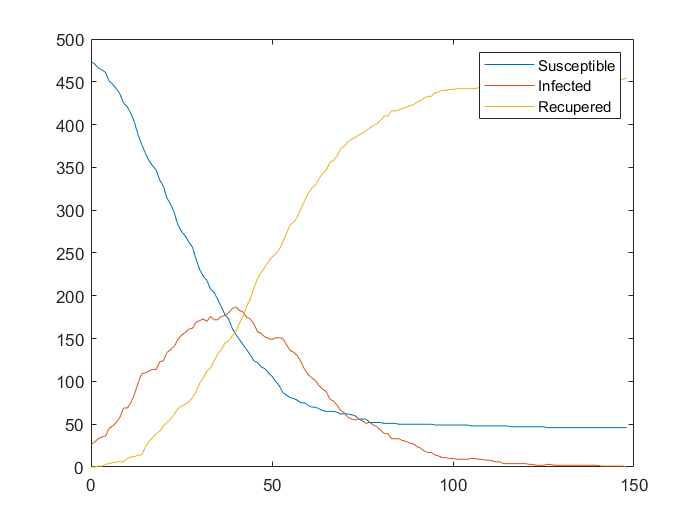

clear;
datos = readmatrix('datos_caso_1.csv');

t = datos(8:end,1)';
ii = datos(8:end,2)';
rr = datos(8:end,6)';
ss = datos(8:end,10)';
plot(t,ss,t,ii,t,rr)
legend({'Susceptible','Infected','Recupered'})

for n = 2:length(t)-1
    ds(n) = ss(n+1)-ss(n);
    di(n) = ii(n+1)-ii(n);
    dr(n) = rr(n+1)-rr(n);
end

ds(n+1) = ss(n)-ss(n-1);
di(n+1) = ii(n)-ii(n-1);
dr(n+1) = rr(n)-rr(n-1);
N = 500;

ff = @(x)  sum((ds + x(:,1).*ss.*ii/N).^2 + (di - (x(:,1).*ss.*ii)/N + x(:,2).*ii).^2 + (dr - x(:,2).*ii).^2);

for kk = 1:10
    rng shuffle
    %opciones de optimización
%     options = optimoptions('gamultiobj',...%'PlotFcn',@gaplotbestf,...
%              'MaxGenerations',1000,...
%              'MaxStallGenerations',500,...
%              'PopulationSize',length(ds),...
%              "FunctionTolerance",1E-15,...
%              'UseVectorized',true);
    [solution funval(kk)] = ga(ff,2,[],[],[],[],[0 0]);
    
    beta(kk)=solution(1);
    gamma(kk)=solution(2);
    
    r0(kk)= beta(end)/gamma(end);
end

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


mean(r0)

ans = 2.7047

std(r0)

ans = 3.8944e-04

clear;
for jj = 1:10
    numero_archivo = char(string(jj));
    nombre_completo = ['datos_caso_2_' numero_archivo '.csv'];
    datos = readmatrix(nombre_completo);
    t = datos(8:end,1)';
    ii = datos(8:end,2)';
    rr = datos(8:end,6)';
    ss = datos(8:end,10)';
    ds = 0;
    di = 0;
    dr = 0;
    for n = 2:length(t)-1
        ds(n) = ss(n+1)-ss(n);
        di(n) = ii(n+1)-ii(n);
        dr(n) = rr(n+1)-rr(n);
    end
    
    ds(n+1) = ss(n)-ss(n-1);
    di(n+1) = ii(n)-ii(n-1);
    dr(n+1) = rr(n)-rr(n-1);
    N = 500;
    
    ff = @(x)  sum((ds + x(:,1).*ss.*ii/N).^2 + (di - (x(:,1).*ss.*ii)/N + x(:,2).*ii).^2 + (dr - x(:,2).*ii).^2);
    

    rng shuffle
    %opciones de optimización
%     options = optimoptions('gamultiobj',...%'PlotFcn',@gaplotbestf,...
%              'MaxGenerations',1000,...
%              'MaxStallGenerations',500,...
%              'PopulationSize',length(ds),...
%              "FunctionTolerance",1E-15,...
%              'UseVectorized',true);
    [solution funval(jj)] = ga(ff,2,[],[],[],[],[0 0]);
    
    beta(jj)=solution(1);
    gamma(jj)=solution(2);
    
    r0(jj)= beta/gamma;

    
end

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


mean(r0)

ans = 1.5748

std(r0)

ans = 0.0923